# Lead compensator design with Bode diagrams

This live script needs the control toolbox. Once profficient, students will probably find that the methods used in this script are mostly performed using sisotool. We also assume the students are already comfortable with the design procedures in the file: **proportional_design_with_bode.mlx**

This script assumes the following block diagram with system G(s) and compensator M(s). 

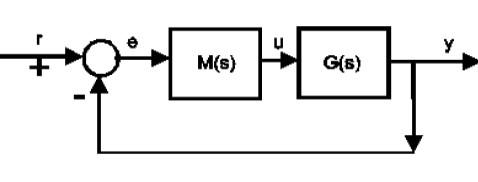

## Lead compensator properties 

The closed-loop transfer function is:   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$ and the intention is to design the compensator M(s) to have the following stucture.


$$M\left(s\right)=K\frac{s+\;a}{s+r\;a}$$
      

Core properties of this compensator are that the high frequency gain is 'r' times bigger than the low frequency gain and secondly, the system has positive phase in the regions near the corner frequencies: *a, ra*. 

The intention is to exploit the phase characteristic (and ignore the gain characteristic), so the final gain cross-over frequency $w_c$ should lie in between the pole and zero corner frequencies, that is:

 
$$a<w_c <r\;a,\;\;\;\;\;\;\;\;\;\;\;1\le r\le 10$$


 An easy way to ensure this requirement is to place the gain cross-over frequency as being the geometric mean of the pole and zero, that is:

${\left(w_c \right)}^2 =r\;a^{2\;\;} \;\;\;\;\;\Longrightarrow \;\;\;\;\;M\left(s\right)$$=K\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$;        $1\le r\le 10$   

The core characteristics are shown in the bode diagram here for: $M\left(s\right)=3\frac{s+0\ldotp 5}{s+2}$ . You can change the values in line 2 to show other examples.

figure; clf
wc2=1; r=4; K=3;
zero = -wc2/sqrt(r);pole = zero*r;  
phasepeak = -atan((1/sqrt(r) - sqrt(r))/2)*180/pi;
M2=tf(K*[1 -zero],[1 -pole])

M2 =
 
  3 s + 1.5
  ---------
    s + 2
 
Continuous-time transfer function.



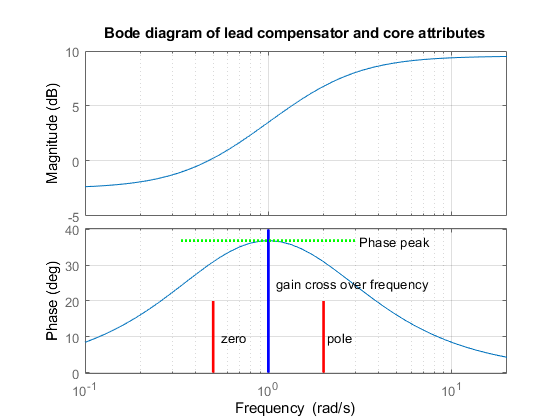

bode(M2,{wc2/10,wc2*20});grid; hold on
plot([-pole,-pole],[20,0],'r-','linewidth',2)
text(-pole*1.05,10,'pole')
plot([-zero,-zero],[20,0],'r-','linewidth',2)
text(-zero*1.1,10,'zero')
plot([wc2,wc2],[40,0],'b-','linewidth',2)
text(wc2*1.1,25,'gain cross over frequency')
plot([wc2/3,wc2*3],phasepeak*[1,1],'g:','linewidth',2)
text(wc2*3.1,phasepeak,'Phase peak')
title('Bode diagram of lead compensator and core attributes')


disp('BELOW is SECTION 1')

BELOW is SECTION 1


disp(' ');

## Section 1: Design approach

Frequency response design of M(s) focuses on the gain and phase margins as core indicators of likely closed-loop behaviour and indeed, in practice, it is only the phase margin that is used actively.  In the following we set out 3 typical design criteria which can be used to underpin systematic design.

- phase margin.

- offset   (not used in simple lead design).

- bandwidth/cross-over frequency .

## a) Phase margin as a core design parameter

Typical statements are that the expected damping ratio of the closed-loop is linked to the phase margin as given here.

disp('Links between PM, damping ratio and expected overshoot')

Links between PM, damping ratio and expected overshoot


damping_ratio = 0.4:.05:.9

damping_ratio =     0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000


overshoot = exp(-damping_ratio*pi./sqrt(1-damping_ratio.^2))

overshoot =     0.2538    0.2053    0.1630    0.1263    0.0948    0.0681    0.0460    0.0284    0.0152    0.0063    0.0015


PM =atan(2*damping_ratio./sqrt(-2*damping_ratio.^2+sqrt(1+4*damping_ratio.^4)))*180/pi

PM =    43.1176   47.6312   51.8273   55.6830   59.1873   62.3410   65.1564   67.6540   69.8600   71.8034   73.5137


One can determine the expected PM from desired overshoot or damping. So, given a desired overshoot of no more than 5-10% is common and thus a damping ratio of around 0.6, it is common to expect a PM of about 60 degrees to be  reasonable. More importantly, one expects that as the PM increases, damping increases and overshoot reduces so PM can also be used in a relative or incremental sense.

For a lead design, we need to know how much phase change is possible, so we tabulate the phase peak of *M(s)* and its dependence upon* r* here. It can be show that the phase peak is given by:


$$\theta =-\tan^{-1} \left(\frac{\frac{1}{\sqrt{r}}-\sqrt{r}}{2}\right)\;\;\;\;\;\;\;\;\;\;\;\equiv \;\;\;\;\;\;\;\;\;\;\;\;\;\;r=\frac{\sin \left(\theta \right)+1}{1-\sin \left(\theta \right)}$$


The figure also illustrates this.

r=logspace(0,1,20)

r =     1.0000    1.1288    1.2743    1.4384    1.6238    1.8330    2.0691    2.3357    2.6367    2.9764    3.3598    3.7927    4.2813    4.8329    5.4556    6.1585    6.9519    7.8476    8.8587   10.0000


phasepeak = -atan((1./sqrt(r) - sqrt(r))/2)*180/pi

phasepeak =          0    3.4697    6.9267   10.3585   13.7532   17.0994   20.3865   23.6050   26.7465   29.8035   32.7698   35.6405   38.4117   41.0805   43.6452   46.1050   48.4596   50.7099   52.8572   54.9032


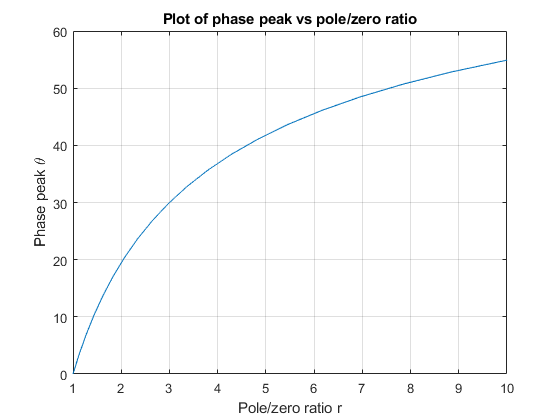

figure; clf
plot(r,phasepeak);grid
xlabel('Pole/zero ratio r')
ylabel('Phase peak \theta')
title('Plot of phase peak vs pole/zero ratio')

In summary, once we know the required phase rotation $\theta$, we can find the required pole/zero ratio *r*.

## b) Offset as a core design criteria

When using a lead design, a core attribute of the bode diagram above is a loss of gain at low frequency. Hence, low frequency gain is not a criteria which can reasonably be tackled with only a lead compensator. Hence, in this note, the offset criteria is considered no further beyond restating how offset can be computed. Typically, one might assume that an integrator is present and thus offset to constant targets is zero.

**Offset to steps**: For a simple fbk loop with system G(s) and compensator M(s) and no integrator, offset to a constant unity reference is given by the formula: $e_{\textrm{ss}} =\frac{1}{1+G\left(0\right)M\left(0\right)}$

## c) Bandwidth as a design criteria for lead design

A lead compensator is a high gain design approach which focuses on managing damping and bandwidth/speed of response. Bandwidth is reasonably represented by the gain cross over frequency of the loop transfer function. Bandwidth is the range of frequencies for which gain is significant. For a closed-loop system where the target gain is unity, significant could be interpreted as something like:  $\textrm{Gain}\ge \sqrt{\frac{1}{2}}$$\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\equiv -3\textrm{dB}\right)$ 

It so happens that we normally plot the Bode diagrams of the open-loop (i.e. loop transfer function) so we cannot infer the closed-loop gain explicitly. However, to a reasonable level of approximation:

$\left|G\left(jw_c \right)M\left(jw_c \right)\right|=1\;\;\Rightarrow \;\left|G_c \left(jw_c \right)\right|\approx$$\sqrt{\frac{1}{2}}$     where $G_c$ is the closed-loop transfer function.

In other words, the gain cross-over frequency $w_c$ which is where $\left|G\left(jw_c \right)M\left(jw_c \right)\right|=1,$ can be taken, approximately, to be the closed-loop bandwidth. This observation is useful because the gain cross-over frequency is an easier quantity to work with in frequency response/bode diagram based design.

It is worth at this point considering what we know about $\left|M\left(jw_c \right)\right|$given the structure is well defined.


$$M\left(jw_c \right)$$

$$=K\left(\frac{{\textrm{jw}}_c +\frac{w_c }{\sqrt{r}}}{jw_c +w_c \sqrt{r}}\right)\;\;\Longrightarrow \;\;\;$$
 
$$\left|M\left(jw_c \right)\right|=\frac{K}{\sqrt{r}}$$


Consequently, we can force $w_c$ to be the gain cross over frequency with the following choice of K: 


$$\left|G\left(jw_c \right)M\left(jw_c \right)\right|=1\;\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;\;\left|G\left(jw_c \right)\right|\frac{K}{\sqrt{r}}=1\;\;\;\Longrightarrow \;\;\;\;\;\;\;\;K=\frac{\sqrt{r}}{\left|G\left(jw_c \right)\right|}$$


## Section 2: Simple lead design using phase margin and bandwidth criteria

For this section, assume the system includes an integrator so that the offset to constant targets is zero. We want to design the parameters of the compensator M(s) so that we have a desirable phase margin and bandwidth. The process can be systemised as follows into several key steps:

- Specify the desired **CRITERIA**:  phase margin $\phi$ (equivalently damping ratio - see section 1a) and desired bandwidth (gain cross over frequency) $w_c$.  If these turn out to be poor or unreasonable choices it will be evident following the later design steps.

- Determine how much phase change $\theta$ is required so that $\arg \left(G\left(jw_c \right)M\left(jw_c \right)\right)=-180+\phi$. Recall that $\arg \left(M\left(jw_c \right)\right)=\theta$ as given in section 1a and so this reduces to:  $\theta =-\arg \left(G\left(jw_c \right)\right)-180+\phi$

- As the phase rotation is known, determine the required pole/zero ratio *r* from the formula: $\;\;\;\;\;\;\;\;\;\;\;\;\;\;r=\frac{\sin \left(\theta \right)+1}{1-\sin \left(\theta \right)}$

- Force the required gain cross-over frequency by choosing the proportional component of *M(s)*, that is *K*,  so that: $\;K=\frac{\sqrt{r}}{\left|G\left(jw_c \right)\right|}$   (see section 1c).

Note, as mentioned above the full compensator structure reduces to this:


$$M\left(s\right)$$

$$=K\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$$


## Example 1

The procedure will be clear following some illustration here. 

STEP 1: Data entry G(s) and definition of target PM and cross over frequency and starting bode diagram.

G=tf(1,[1 5 8 0]);
wc=2;
desiredPM = 60;
[gainGwc,phaseGwc] = bode(G,wc);

wmin=0.1;
wmax=6;
figure; clf
bode(G,{wmin,wmax});grid;hold on
plot([wmin,wmax],[-180+desiredPM]*[1 1],'r')
text(wmin*10,-180+desiredPM+10,'-180+\phi')
plot([wc,wc],[-180+desiredPM,-90],'g','linewidth',3)
text(wc*1.1,-180+desiredPM+15,'wc')


STEP 2: Determine the required uplift at the gain cross over frequency $w_c$ to achieve the target PM; for this design the uplift can be determined explicitly as seen in the code below. You need to ensure the required uplift is between about 10 and 60 degrees, or the required pole/zero ratio will be outside of bounds (see section 1a). **If the required uplift is too large, the desired bandwidth will need reducing.**

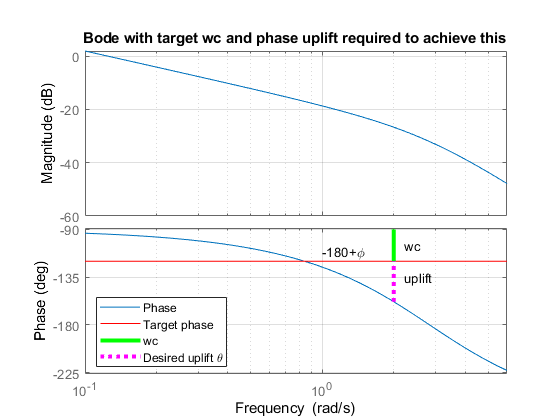

uplift = -180 - phaseGwc +desiredPM;
plot([wc,wc],[phaseGwc,-180+desiredPM],'m:','linewidth',3)
text(wc*1.1,-180+desiredPM-15,'uplift')
legend('Phase','Target phase','wc','Desired uplift \theta','Location','Southwest')
title('Bode with target wc and phase uplift required to achieve this')

disp('*****************************************')

*****************************************


disp(['Identified a suitable uplift as ',num2str(uplift),'deg'])

Identified a suitable uplift as 38.1986deg


STEP 3: Determine the required pole/zero ratio* r* from: $\;\;\;r=\frac{\sin \left(\theta \right)+1}{1-\sin \left(\theta \right)}$.  Again a reminder that this should be within the bounds $1\le r\le 10$ and if not, the bandwidth and/or PM criteria will need to be relaxed.

disp('*****************************************')

*****************************************


disp('Pole/zero ratio')

Pole/zero ratio


upliftrad=uplift*pi/180;
r = (sin(upliftrad)+1)/(1-sin(upliftrad))

r = 4.2409

STEP 4: Determine the proportional term required to ensure the bandwidth requirement is met, that is: $\;K=\frac{\sqrt{r}}{\left|G\left(jw_c \right)\right|}$ . The figure should show that the desired cross-over frequency has been achieved, that is the magenta (0dB) and green ($w_c$)  intersection should also lie on the compensated gain plot.

sr=sqrt(r);

Final compensator


K= sr/gainGwc

K = 44.3598

zero = wc/sr;
pole = wc*sr;
disp('Final compensator');

M =
 
  44.36 s + 43.08
  ---------------
     s + 4.119
 
Continuous-time transfer function.



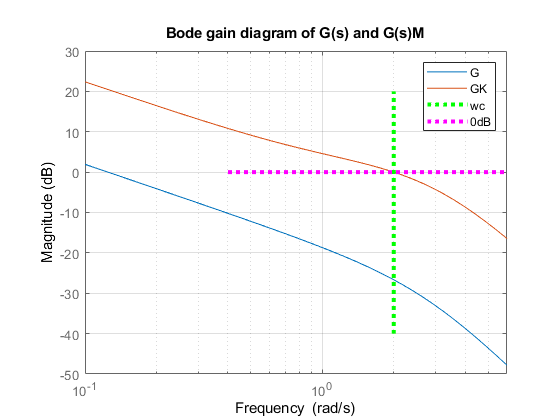

M = K*tf([1,zero],[1,pole])

figure; clf
bodemag(G,G*M,{wmin,wmax});grid;hold on
plot([wc,wc],[-40,20],'g:','linewidth',3)
plot([wc/5,wc*5],[0,0],'m:','linewidth',3)
title(['Bode gain diagram of G(s) and G(s)M'])
legend('G','GK','wc','0dB')

## Check the final design

You should ensure that the phase margins and bandwidth criteria have been met and also that pole/zero ratio is within sensible limits.

If the design is correct, you would expect the compensated system to have:

- A PM exactly equal to the target PM .

- A cross over frequency exactly equal to the one specified.

- The phase lift around the cross-over frequency should be evident when one overlays the compensated and uncompensated plots.

disp('******************************************************')

******************************************************


disp('CHECK MARGINS OF FINAL DESIGN')

CHECK MARGINS OF FINAL DESIGN


disp(['Target phase margin was ',num2str(desiredPM)])

Target phase margin was 60


disp(['Target cross-over frequency was ',num2str(wc)])

Target cross-over frequency was 2


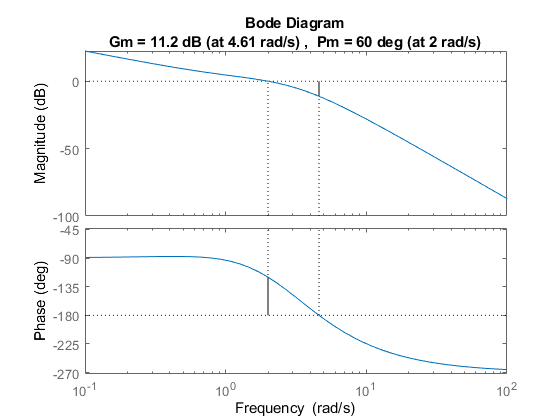

figure; clf
margin(G*M)

disp('*****************************************')

*****************************************


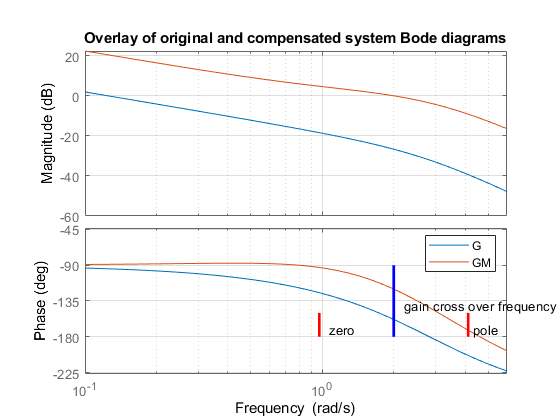

figure; clf
bode(G, G*M,{wmin,wmax});grid; hold on
plot([pole,pole],[-180,-150],'r-','linewidth',2)
text(pole*1.05,-170,'pole')
plot([zero,zero],[-180,-150],'r-','linewidth',2)
text(zero*1.1,-170,'zero')
plot([wc,wc],[-180,-90],'b-','linewidth',2)
text(wc*1.1,-120,'gain cross over frequency')
legend('G','GM')
title('Overlay of original and compensated system Bode diagrams')


disp('BELOW is SECTION 3')

BELOW is SECTION 3


disp(' ');

### Section 3: Remarks and student independent study

- One should note that the choice of PM  never had a precise link with damping/behaviour in the first place, and thus some fine tuning will typically be required anyway.

- Typical text books assume an integrator is already in the system or one would like end up with a large offset using a lead only design.

Step responses are included below for completeness. Ultimately we need to overlay this will the alternative of a lag design and a lead-lag design. This is in another script file.

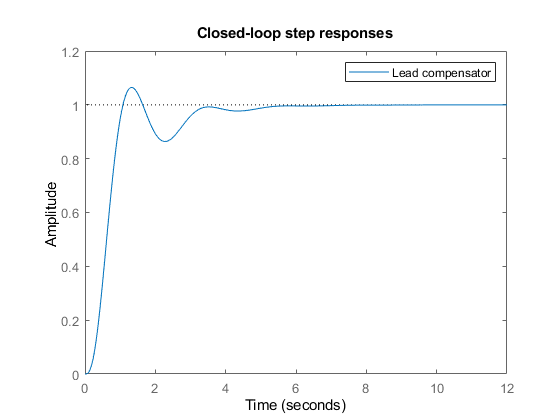

figure;clf
GcM=feedback(G*M,1);
step(GcM);
title('Closed-loop step responses')
legend('Lead compensator')